# ECE 2409

#### Fall 2020

#### Theo Andonyadis

#### Homework 3

Question 1

Part A

A= load("students.mat","students")

A = struct with fields:
    students: [5×10 double]


B= [A.students]

B =    100    90    95    80   100   100    90    95    93    94
    75    60    40    45    60    65    70    75    90    79
    85    90    80    75   100    60    90    84    86    88
    40   100   100    64    90    70    90    88    76    89
    60    65    70    73    75    80    85    88    90   100


fprintf('\t%3d\t%3d\t%3d\t%3d\t%3d\t%3d\t%3d\t%3d\t%3d\t%3d\n', B')

	100	 90	 95	 80	100	100	 90	 95	 93	 94
	 75	 60	 40	 45	 60	 65	 70	 75	 90	 79
	 85	 90	 80	 75	100	 60	 90	 84	 86	 88
	 40	100	100	 64	 90	 70	 90	 88	 76	 89
	 60	 65	 70	 73	 75	 80	 85	 88	 90	100


Part B

C= [sum(B(1,:))/10, sum(B(2,:))/10, sum(B(3,:))/10, sum(B(4,:))/10, sum(B(5,:))/10];
%or mx=mean(x,2);
fprintf('%.2f\n', C)

93.70
65.90
83.80
80.70
78.60


Part C

S1= 0.25*sum(B(1,1:7))/7 + 0.4*sum(B(1,8:9))/2 + 0.35*sum(B(1,10));
S2= 0.25*sum(B(2,1:7))/7 + 0.4*sum(B(2,8:9))/2 + 0.35*sum(B(2,10));
S3= 0.25*sum(B(3,1:7))/7 + 0.4*sum(B(3,8:9))/2 + 0.35*sum(B(3,10));
S4= 0.25*sum(B(4,1:7))/7 + 0.4*sum(B(4,8:9))/2 + 0.35*sum(B(4,10));
S5= 0.25*sum(B(5,1:7))/7 + 0.4*sum(B(5,8:9))/2 + 0.35*sum(B(5,10));
D= [S1, S2, S3, S4, S5]

D =    93.8929   75.4714   85.5143   83.7357   88.7429


%OR M=mean(x(:,1:7),2)*0.25 ...
%fprintf('%4.2f\n',M)
fprintf('%.2f\n', D)

93.89
75.47
85.51
83.74
88.74


Question 2

x=0:1e-2:4

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


y= 1./((x-3).^2 + 0.1) + 1./((x-2).^2 + 0.05) +2

y =     2.3568    2.3600    2.3632    2.3665    2.3698    2.3732    2.3766    2.3801    2.3836    2.3871    2.3907    2.3944    2.3981    2.4019    2.4057    2.4096    2.4135    2.4175    2.4216    2.4257    2.4299    2.4341    2.4385    2.4428    2.4473    2.4518    2.4564    2.4610    2.4658    2.4706    2.4755    2.4804    2.4855    2.4906    2.4958    2.5011    2.5065    2.5119    2.5175    2.5232    2.5289    2.5348    2.5407    2.5468    2.5529    2.5592    2.5656    2.5721    2.5787    2.5854


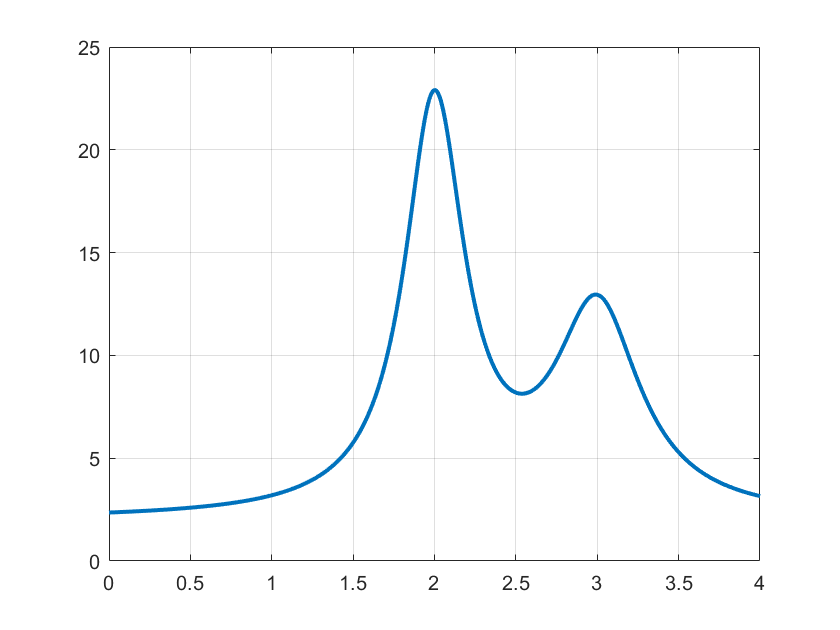

figure
plot(x,y,'linewidth',2);grid